# **繪圖軟體應用 第4周(2019/10/2)**

## **繪圖方法**

**目的 : 節省時間**

clear;clc;clf
help graph2D

  Two dimensional graphs.
  
  Elementary X-Y graphs.
    plot      - Linear plot.
    loglog    - Log-log scale plot.
    semilogx  - Semi-log scale plot.
    semilogy  - Semi-log scale plot.
    polar     - Polar coordinate plot.
    plotyy    - Graphs with y tick labels on the left and right.
 
  Axis control.
    axis       - Control axis scaling and appearance.
    zoom       - Zoom in and out on a 2-D plot.
    grid       - Grid lines.
    box        - Axis box.
    rbbox      - Rubberband box.
    hold       - Hold current graph.
    axes       - Create axes in arbitrary

doc plot

點與點的資料連線

figure(1)
x=-2*pi:0.4:2*pi;
y=sin(x);
whos

  Name      Size            Bytes  Class     Attributes

  x         1x32              256  double              
  y         1x32              256  double              



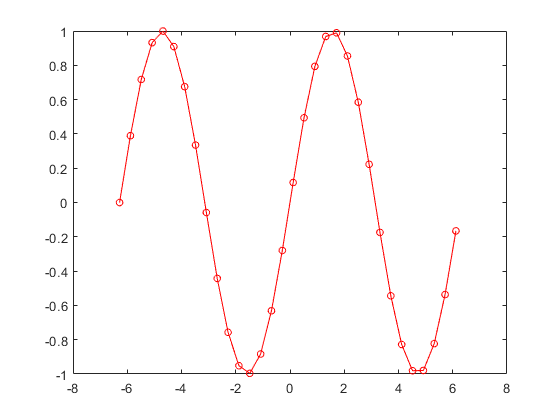

plot(x,y,'ro-','MarkerSize',5)

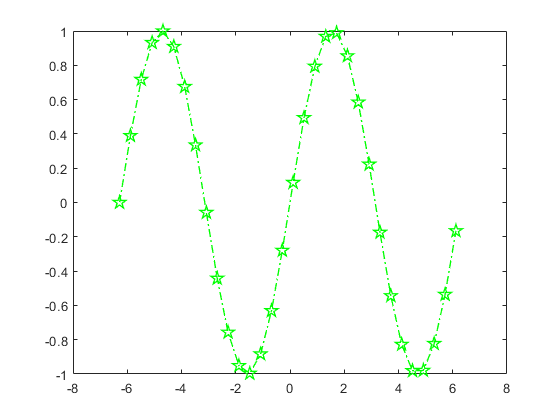

plot(x,y,'gp-.','MarkerSize',10,'LineWidth',1)

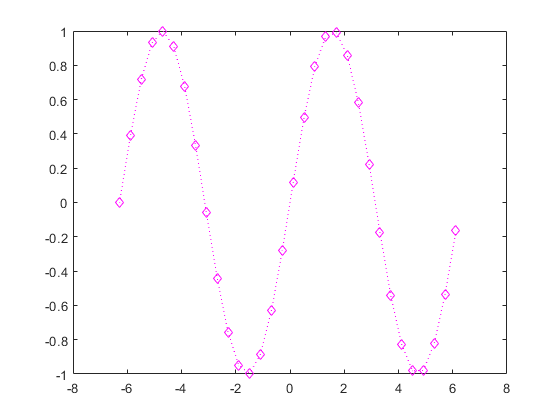

h =   Line with properties:

              Color: [1 0 1]
          LineStyle: ':'
          LineWidth: 0.0100
             Marker: 'diamond'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×32 double]
              YData: [1×32 double]
              ZData: [1×0 double]

  Show all properties


h = plot(x,y,'md:','LineWidth',0.01,'MarkerEdgeColor','auto')

%指定性質給h變數
%注意 RGB 配色三原色
get(h)   %顯示所有性質

    AlignVertexCenters: 'off'
            Annotation: [1×1 matlab.graphics.eventdata.Annotation]
          BeingDeleted: 'off'
            BusyAction: 'queue'
         ButtonDownFcn: ''
              Children: [0×0 GraphicsPlaceholder]
              Clipping: 'on'
                 Color: [1 0 1]
             CreateFcn: ''
       DataTipTemplate: [1×1 matlab.graphics.datatip.DataTipTemplate]
             DeleteFcn: ''
           DisplayName: ''
      HandleVisibility: 'on'
               HitTest: 'on'
         Interruptible: 'on'
              LineJoin: 'round'
             LineStyle: ':'
             LineWidth: 0.0100
                Marker: 'diamond'
       MarkerEdgeColor: 'auto'
       MarkerFaceColor: 'none'
         MarkerIndices: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32]
            MarkerSize: 6
                Parent: [1×1 Axes]
         PickableParts: 'visible'
              Selected: 'off'
    SelectionHighlight: 'on'
           

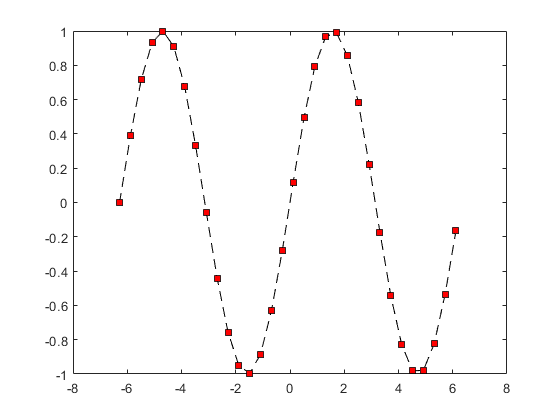

plot(x,y,'ks--','LineWidth',0.01,"MarkerFaceColor",'r')

手動調整線條配色*   'color',[135 53 36]/255*

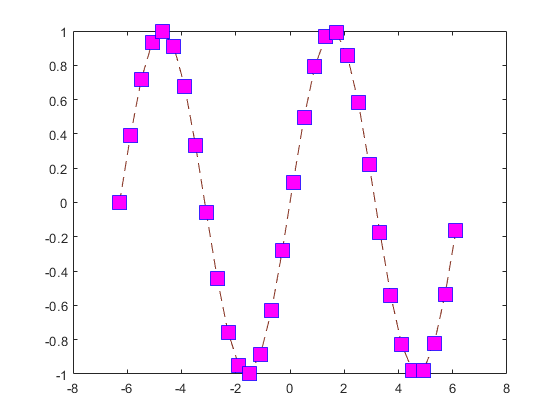

% set(h,'color',[135 53 36]/255)
plot(x,y,'s--','MarkerSize',14,'LineWidth',0.01,...
    'color',[135 53 36]/255,'MarkerEdgeColor','b',...
    "MarkerFaceColor",'m')

### 多線段

x1=linspace(-4*pi,4*pi);
y1=sin(x1);
y2=cos(x1);
h = plot(x1,y1,'h-',x1,y2,'g--')

h =   2×1 Line array:

  Line
  Line


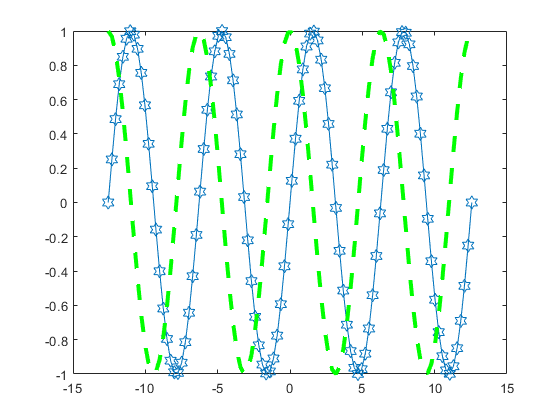

hold off
%-----------------------------------------
set(h(2),'LineWidth',3)
set(h(1),"MarkerSize",10)

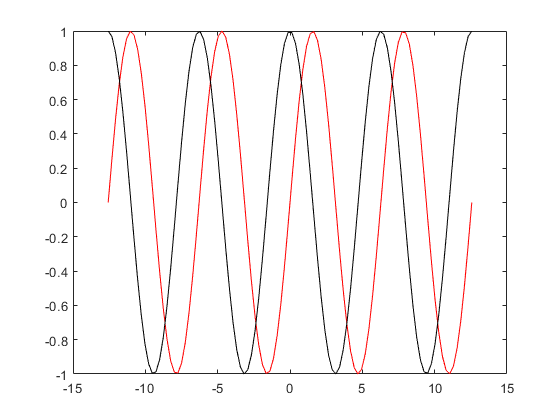

plot(x1,y1,'r-')
hold on
plot(x1,y2,'k')
hold off

logspace

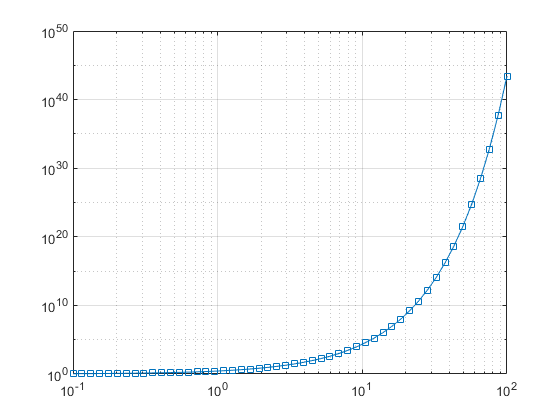

x2 = logspace(-1,2);
y3=exp(x2);
loglog(x2,y3,'s-') % x 軸和 y軸都以log呈現
grid on

semilogx

y4=0.1:0.1:1

y4 =     0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000


x4 = log(y4)

x4 =    -2.3026   -1.6094   -1.2040   -0.9163   -0.6931   -0.5108   -0.3567   -0.2231   -0.1054         0


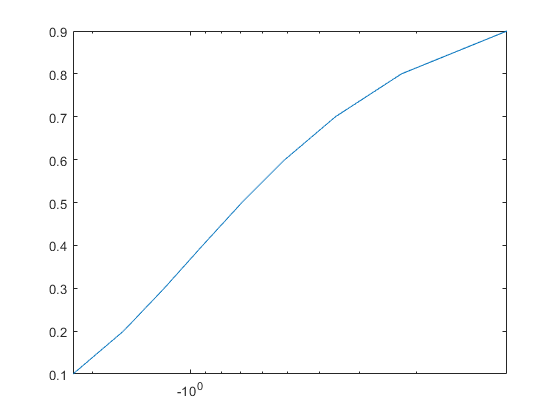

semilogx(x4,y4)

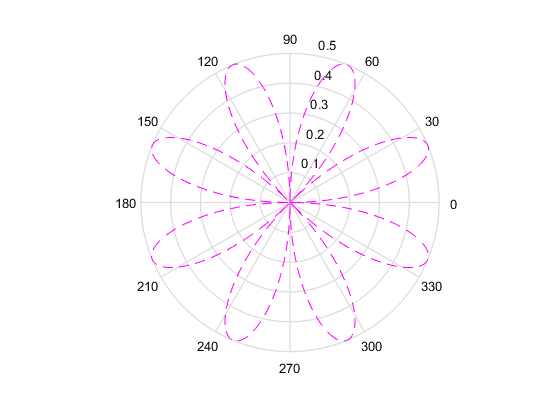

theta = 0:0.01:2*pi;  %徑度
rho = sin(2*theta).*cos(2*theta);

figure
polar(theta,rho,'--m')

### 風玫瑰圖

% wind_rose(90,1)  % wind_rose 是函式

% plot_wind

% doc plotyy
x5 = -2*pi:0.2:2*pi;
y5 = sin(x5);
y6 = 200*cos(x5);
[AX,H1,H2] = plotyy(x5,y5,x5,y6,'plot','stem')

AX =   1×2 Axes array:

    Axes    Axes


H1 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×63 double]
              YData: [1×63 double]
              ZData: [1×0 double]

  Show all properties


H2 =   Stem with properties:

              Color: [0.8500 0.3250 0.0980]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 6
    MarkerFaceColor: 'none'
          BaseValue: 0
              XData: [1×63 double]
              YData: [1×63 double]

  Show all properties


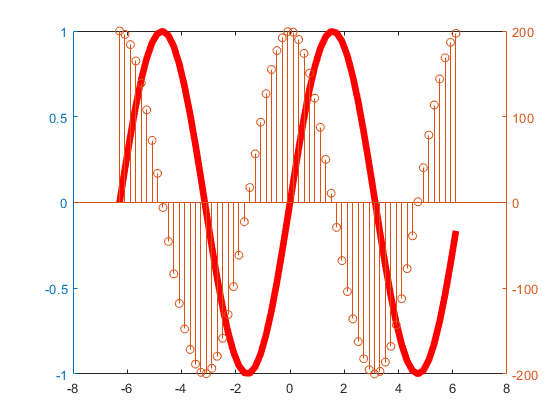

set(H1,'color','r','LineWidth',5)  %改掉第1個線段特性